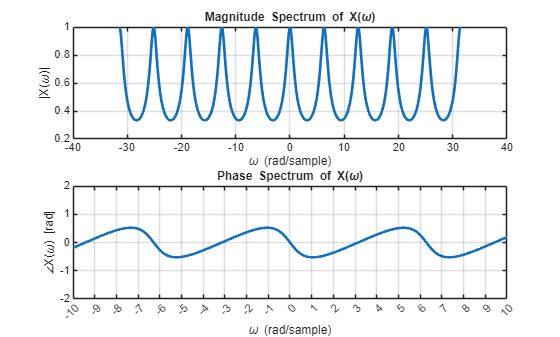

% DTFT of x[n] = 0.5*(0.5)^n * u[n]
omega = -10*pi:0.001:10*pi;           % กำหนดช่วงความถี่
X = 0.5 ./ (1 - 0.5*exp(-1j*omega)); 

% Magnitude and Phase
magX = abs(X);
phaseX = angle(X);

% Plot
figure;
subplot(2,1,1);
plot(omega, magX, 'LineWidth', 2);
xlabel('\omega (rad/sample)');
ylabel('|X(\omega)|');
ylim([0.2 1]);
title('Magnitude Spectrum of X(\omega)');
grid on;

subplot(2,1,2);
plot(omega, phaseX, 'LineWidth', 2);
xlabel('\omega (rad/sample)');
ylabel('∠X(\omega) [rad]');
xlim([-10 10]);
xticks(-10:1:10);
ylim([-2 2]);
title('Phase Spectrum of X(\omega)');
grid on;